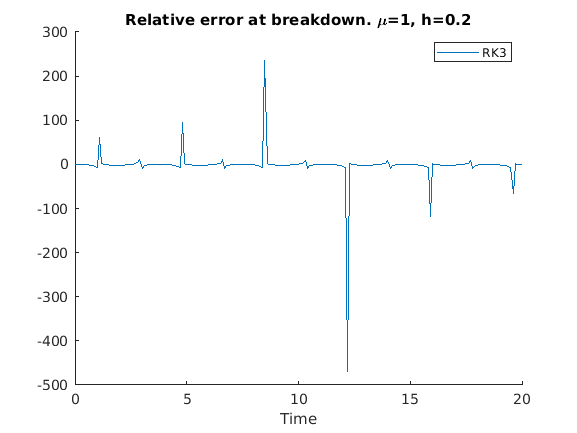

clearvars
tic
u=1; %fixed u and fixed h
f = @(x,y) y;
g = @(x,y) u*(1-x^2)*y-3*x;
t=[0:0.1:20]';
l=length(t);
x=zeros(l,2);
x(1,1)=2;
x(1,2)=0;
h=0.2;

for i=1:l-1
    k1=zeros(1,2);
    k2=zeros(1,2);
    k3=zeros(1,2);
    k1(1,1) = f(x(i,1),x(i,2));
    k1(1,2) = g(x(i,1),x(i,2));
    
    k2(1,1) = f(x(i,1)+h*k1(1,1)/2, x(i,2)+h*k1(1,2)/2);
    k2(1,2) = g(x(i,1)+h*k1(1,1)/2, x(i,2)+h*k1(1,2)/2);
    
    
    k3(1,1) = f(x(i,1)-h*k1(1,1)+2*h*k2(1,1),x(i,2)-h*k1(1,2)+2*h*k2(1,2));
    k3(1,2) = g(x(i,1)-h*k1(1,1)+2*h*k2(1,1),x(i,2)-h*k1(1,2)+2*h*k2(1,2));
    x(i+1,:) = x(i,:) + (h/6)*(k1+4*k2+k3);
end
%plot(t,x)
%legend('x','y')
%xlabel('Time')
%grid()
%title('Solution & Derivative (prebreakdown) mu=6, h=0.1')
options = odeset('RelTol',10^-4,'AbsTol',10^-6);
f=@(t,x0) [x0(2), u*(1-x0(1)^2)*x0(2)-3*x0(1)]';
y0=[2;0];
t= [0:0.1:20]';
[t0,x0]=ode45(f,t,y0,options);
%   
f=@(t,x1) [x1(2), u*(1-x1(1)^2)*x1(2)-3*x1(1)]';
[t0,x1]=ode23s(f,t,y0,options);
errorvec = x-x1; %Calculates error between RK3 and ode23s
for k=1:l
    errorvec(k,1)=errorvec(k,1)/x1(k,1); %calcs %error
end
hold on
%plot(t,x0(:,1),'ro')
%plot(t,x1(:,1),'b--')
%plot(t,x(:,1),'g+')
plot(t,errorvec(:,1))
legend('RK3')
%legend('ode45','ode23s','RK3','Error')
xlabel('Time')
title("Relative error at breakdown. \mu="+u+", h="+h)
% title('Solution Comparison, u=7.36,h=0.1')
hold off

[maxerror,position]=max(abs(errorvec(:,1)))

maxerror = 470.4636

position = 123

errorvec_rk3=errorvec;
timetaken=toc

timetaken = 0.2845